# Resumen de DSP

## Señales digitales y sistemas:

### Definiciones preliminares

una señal se define como una cantidad física que varía con el tiempo, el espacio o cualquier otra variable  o variables independientes. Pro ejemplo, las funciones 

- 
$$s_1 \left(t\right)=5t$$


- 
$$s_2 \left(t\right)=20t^2$$


 Describen  dos señales, una que varía linealmente con la variable independiente t (tiempo) y una segunda que varía cuadráticamente  con t. Las señales descritas en (1) y (2) pertenecen  a las clases de señales  que quedan  perfectamente definidas especificando la dependencia funcional con la variable  independiente. Sin embargo, existen casos en los que dicha relación funcional es desconocida  o demasiado complicada como para tener utilidad práctica.

** Por ejemplo,**  una señal de voz no sepuede  dercribrir  funcionalmente mediante expresiones como (1). En general, un segmento de voz puede representarse con un alto grado de exactitud como la suma de varias sinusoides de diferentes amplitudes y frecuencias, esto  es, como.

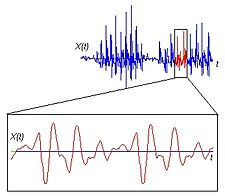

3.  $\sum_{i=1}^{N} A_{i}(t) \sin[2\pi F_{i}(t)t+ \theta_{i}(t)]$

donde ${A_{i}(t)},F_{i}(t)$y $ \theta_{i}(t)$ son los conjuntos (probablemente variables en el tiempo) de amplitudes, frecuencias y fases, respectivamente de las sinussoides. De hecho, una manera de interpretar la información o el mensaje contenido en un segmento corto de señal. 

**Otro ejemplos ** de señales naturales son los electrocardiograms y los electroencefalogramas son ejemplos de señales que portan información  y que varían como funciones de una única variable independiente, el tiempo.  Una imagen constituye un ejemplo de señal que varía en dos variable independientes. Las dos variables independientes en este caso son  las coordenadas espaciales. Estos  son unos pocos ejemplos de un incontable  número de señales naturales  que se pueden encontrar en la práctica.

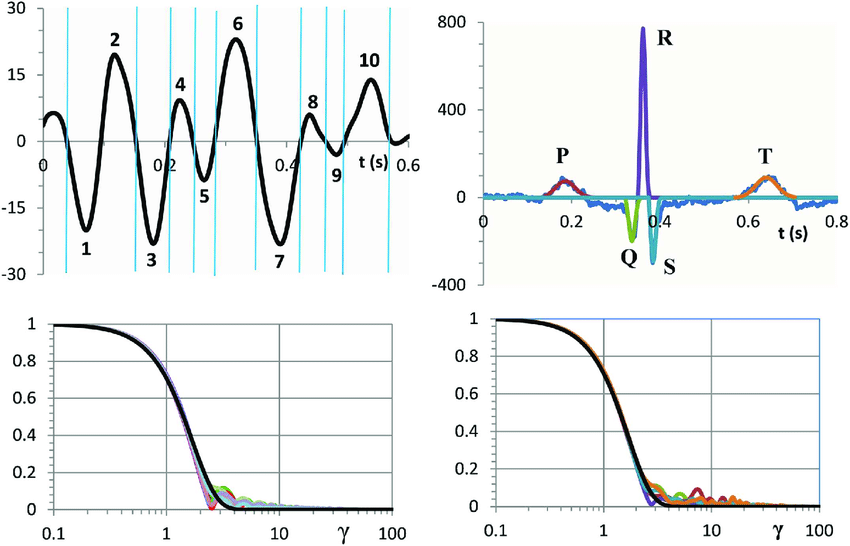

- **Sistema: **se define como un dispositivo físico que realiza una operación sobre una señal. La integración de una o varias componentes la generación de señales está  asociada con un sistema que responde a un estímulo o fuerza.

- **Fuente de señal:  **Se define como  la combinación o integración del estímulo con el sistema.

- **Tratamiento de la señal: ** Cuando pasamos  una señal a través de un sistema, como el caso del filtro, decimos que hemos procesado  o tratado la señal.

- **DSP en  Hardware:  **circuitos lógicos configurado para resolver las operaciones especificadas, permite el procesamiento a muy altas frecuencias. pero son dificiles de configurar.

- **DSP en Software: **es el más usados debido a la versatilidad de aplicabilidad y se implementa sobre una  computadoras,económica, tiene deficiencia con el ancho de banda extrremadamente grandes.

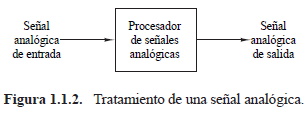

- **A/D: **convertidor analógico-digital, interfaz entre la señal analogica y el procesador digital. la precisión de este va dada por la tipología del dato (INT, Float)

- **D/A: **convertidor digital-analógico, interfaz entre el dominio digital y el analógico.

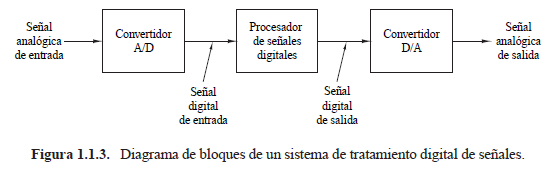

## Clasificación de las Señales.

Como se ha explicado, una señal se describe mediante una función de una o más variables independientes. El valor de la función (es decir, de la variable dependiente) puede ser una magnitud escalar real, una magnitud compleja o incluso un vector. Por ejemplo, la señal

- **Señal real: ** $s_{1}(t)=a\sin(3\pi t)$

- **Señal compleja: **$s_{2}(t)=Ae^{j3\pi t}=A\cos 3\pi t +jA\sin3\pi t$

A=7;
ti=-10; %Instante de inicio
tf=10;  % Instante final
t=ti:0.1:tf;  % Instantes de tiempo
s1=A*sin(3*pi*t);
s2= A*cos(3*pi*t)+ i*A*sin(3*pi*t);
s2r= real(s2);
s2i= imag(s2);
subplot(3,1,1);
plot(t,s1); xlabel('t'); ylabel('s1(t)'); title('Señal Real');grid on
subplot(3,1,2);
plot(t,s2r); xlabel('t'); ylabel('s2(t)'); title('Señal Compleja parte real');grid on
subplot(3,1,3);
plot(t,s2i); xlabel('t'); ylabel('s2(t)'); title('Señal Compleja parte Imaginaria');grid on

- **Multicanal:**


$$S_3 \left(t\right)=\left\lbrack \begin{array}{c}
S_1 \left(t\right)\\
S_2 \left(t\right)\\
S_3 \left(t\right)
\end{array}\right\rbrack$$


- **Unidimensional: **Si la señal es una función de una sola variable independiente .

- **M-dimensional: **si su valor es una función de M variables independientes.

- **Continuas: **o señales analógicas están definidas para cada instante de tiempo  y toman sus valores en un intervalo continuo (a,b), donde a puede ser −∞ y b puede ser ∞.

- **Discretas: **Solo están definidas en determinados instantes especifico  de tiempo. Dichos instantes de tiempo no tienen que ser equisdistantes, aunque, en la práctica, normalmente están igualmente espaciados para facilitar cálculos. La señal x(tn) = e^-|tn|, n = 0, ±1, ±2, . . .es un ejemplo de una señal discreta en el tiempo. Si los instantes de tiempo tn están igualmenteespaciados (es decir, tn = nT ), también se utiliza la notación x(nT).

- **Digital: **Valores de amplitud discretizado.

- **Cuantificación: **El proceso de conversión de una señal continua en una señal discreta 

- **Determinista: **Señal que se pueda describir  unívocamennte  mediante una expresión matemática explicita, una tabla de datos o una regla bien definida.

- **Aleatorias: **Señales que no se puede predecir su valor o su ecuación puede llegar hacer muy díficil de describir.

En la práctica, las señales discretas en el tiempo puede originarse de dos formas:

- **Muestreo **Selaccionando valores de una señal analógica en instantes discretos de tiempo

- Acumulando una variable en un período de tiempo, ej: de los coches por hora.

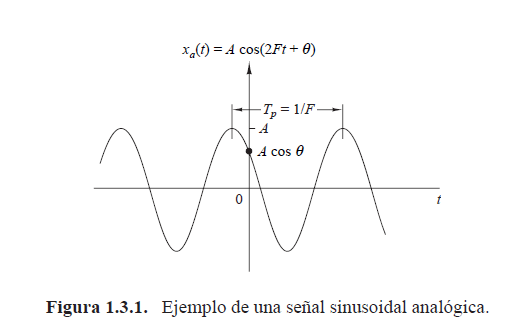


$$x_{a}(t) = Ae^{j(\Omega t +\theta) } \\
e^{\pm j \phi}= cos \phi \pm j sin \phi
$$


**Vídeo: **[https://www.youtube.com/watch?v=rKf92Vgx2ag](https://www.youtube.com/watch?v=rKf92Vgx2ag)

             [https://www.youtube.com/watch?v=w_-aWuxO8eU](https://www.youtube.com/watch?v=w_-aWuxO8eU)

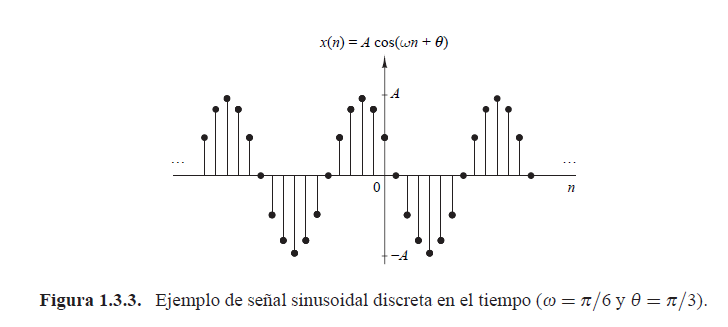

**Nota: **Una sinusoide discreta en el tiempo es periódica sólo si su frecuencia es un número racional por definición, una señal discreta en el tiempo x(n) es periódica de período N (N>0) si y sólo si 

x(n+N) = x(n) para todo n

El valor mínimo de *N* para el que  se cumple es el *periódo fundamental. *

La demostración de la propiedad de periodicidad  es sencilla. Para que una sinusoide de frecuencia *f0 sea períodica, se tiene que cumplir que*

*cos[2π f0(N +n)+θ] = cos(2π f0n+θ )*

*Esta relacion es cierta si y sólo si existe un entero k tal que*

*2πf0N =2kπ *

*o, lo que es lo mismo*

*f0=k/N*

De acuerdo con la ecuación, una señal sinusoidal discreta en el tiempo sólo es periódica si su frecuencia f0 se puede expresar como la relación de dos enteros (es decir, f0 es racional).

Para determinar el período fundamental N de una sinusoide periódica, expresamos su frecuencia f0 como en la ecuación y cancelamos los factores comunes, de modo que k y N sean primos relativos(si no tienen ningún factor primo en común o su MCD es igual a 1). 

Entonces el **período fundamental N** de la sinusoide es igual a N. Observe que una pequeña variación de la frecuencia puede dar lugar a una variación muy grande del período. Por ejemplo, f1 = 31/60 implica que N1 = 60, mientras que f2 = 30/60 da como resultado N2 = 2.

Las señales sinusoidales discretas en el tiempo cuyas frecuencias están separadas un múltiplo entero de 2*π son idénticas.*

Para demostrar esta afirmación, consideramos la señal sinusoidal cos(ω0n+θ)* .  Fácilmente se deduce que *


$$\cos[(\omega _{0} +2\pi  )n+\theta ]= cos(\omega _{0}n+2\pi  n+\theta )= cos(\omega _{0}n+\theta  )$$


por tanto, todas las secuencias sinusoidales 


$$x_{k}(n) = Acos(\omega _{k}n+\theta  ), k = 0,1,2, . . .$$


donde


$$\omega  k =\omega _{0}+2k\pi  , -\pi  \le \omega _{0} \le \pi $$


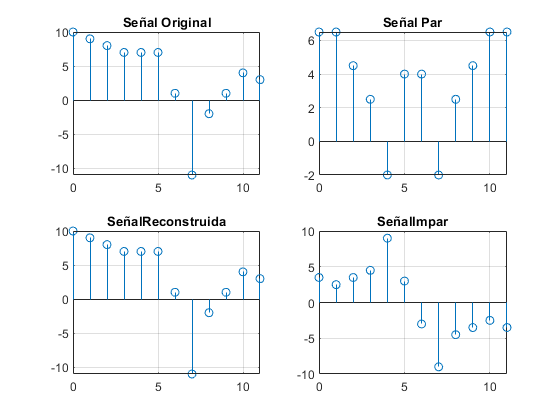

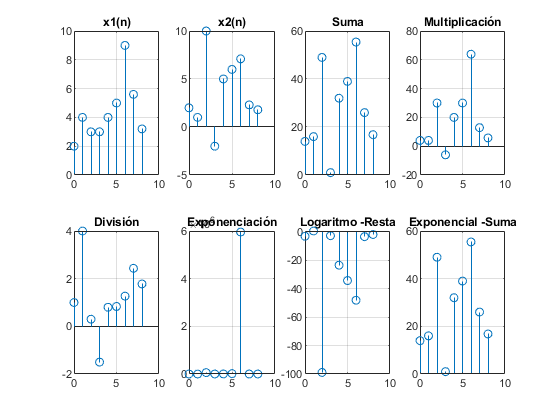

clc; clear all; close all;
%Señal de entrada
x=[10 9 8 7 7 7 1 -4 - 7 -2 1 4 3];
[nf,nc]=size(x);
n=0:nc-1;
% Descomposición parte par e impar
xpar=(x+fliplr(x))/2;
ximpar=(x-fliplr(x))/2;
% Reconstrucción
xrecons=xpar+ximpar;
%Graficación
subplot(2,2,1); stem(n,x); grid on; title('Señal Original')
subplot(2,2,2); stem(n,xpar);grid on; title('Señal Par');
subplot(2,2,3); stem(n,xrecons);grid on; title('SeñalReconstruida');
subplot(2,2,4); stem(n,ximpar); grid on;title('SeñalImpar');

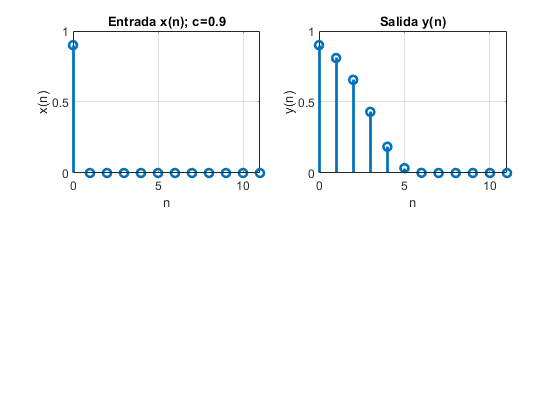

clc; clear all; close all;
%Señales x1(n) y x2(n)
x1=[2 4 3 3 4 5 9 5.6 3.2];
x2= [2 1 10 -2 5 6 7.1 2.3 1.8];
n=0:8;
%Operaciones Matemáticas
x3=3*x1+4*x2; %Suma
x4=x1.*x2; %Multiplicación
x5=x1./x2; %División
x6=x1.^x2; % Exponenciación
x7=log(x1)-x2.^2; %Logaritmo
x8=exp(x1)+x2; %Exponenciación
% Visualización
subplot(2,4,1); stem(n,x1); title('x1(n)');grid on
subplot(2,4,2); stem(n,x2); title('x2(n)') ;grid on
subplot(2,4,3); stem(n,x3); title('Suma') ;grid on
subplot(2,4,4); stem(n,x4); title('Multiplicación');grid on
subplot(2,4,5); stem(n,x5); title('División') ;grid on
subplot(2,4,6); stem(n,x6); title('Exponenciación') ;grid on
subplot(2,4,7); stem(n,x7); title('Logaritmo -Resta');grid on
subplot(2,4,8); stem(n,x3); title('Exponencial -Suma');grid on


Ns=12; % Definición número de muestras
% Entrada x(n)=c d(n)
c=0.9;
x= c*[1 zeros(1,Ns-1)];
yi=0; %condición inicial y(-1)=0
y=zeros(1,Ns);
y(1)=yi^2+x(1);% evaluando para y(n=0)
for n=1:Ns-1
    y(n+1)=y(n)^2+x(n+1);
end
n=0:Ns-1;
subplot(2,2,1);
stem(n,x,'LineWidth',2); xlabel('n'); ylabel('x(n)');
title(['Entrada x(n); c=' num2str(c)]);grid on;
subplot(2,2,2);
stem(n,y,'LineWidth',2);xlabel('n');ylabel('y(n)');title('Salida y(n)');grid on

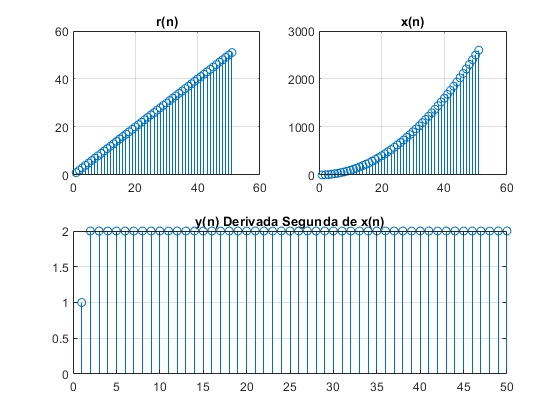

% Sistema que calcula iterativamente la Derivada de una señal

% y(n)=x(n+1)-2x(n)+x(n-1);

clc;clear vars; close all;
L=50; % muestras a visualizar

% Señal r (escalón)
A=2; 
r=A*ones(1,L+1);

% Señal r (exponencial)
%  a=0.9;
%  r=a.^([1:L+1]);

%Señal r (rampa)
r=1:L+1; 


% Señal procesada a una potencia
x=r.^2;

% Valor de y(0)
n=0; m=n+1;
y(m)= x(m); % Se asume y(-1)=0;

for n=1:L-1
   m=n+1;
   y(m)=x(m+1)-2*x(m)+x(m-1);
   
end


subplot(2,2,1); stem(r); title('r(n)'); grid on;

subplot(2,2,2); stem(x); title('x(n)');grid on;

subplot(2,2,3:4); stem(y); title('y(n) Derivada Segunda de x(n)');grid on;

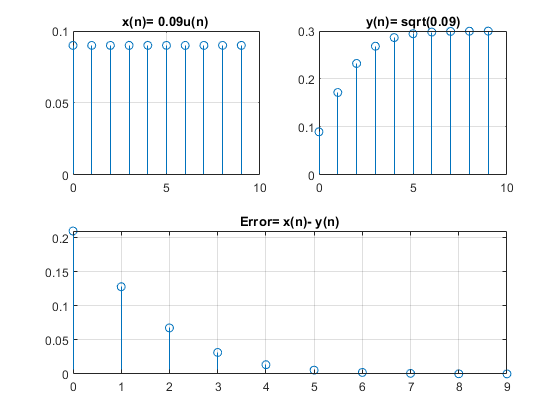

% Sistema que calcula iterativamente la raíz cuadrada de un número 0< a <1;
% y(n)=x(n)-y(n-1)^2+y(n-1);
% x(n)=a u(n); donde  0<a<1;
clc;clearvars; close all;
a=0.09; L=10;
x=a*ones(1,L);

% Valor de y(0)
n=0; m=n+1;
y(m)= x(m); % Se asume y(-1)=0;

for n=1:L-1
   m=n+1;
   y(m)=x(m)-y(m-1)*y(m-1)+y(m-1);
   
end
Err_raiz=sqrt(a)-y; %Error en cada iteración;

subplot(2,2,1); stem([0:L-1],x); title( ['x(n)= ' num2str(a) 'u(n) ']); grid on;
subplot(2,2,2); stem([0:L-1],y); title(['y(n)= sqrt(' num2str(a)  ')']);grid on;
subplot(2,2,3:4); stem([0:L-1],Err_raiz); title('Error= x(n)- y(n)');grid on;



## Clase_03:

Convolución 

- capturar vector X_(n),h(n)

- len h ,x

- creamos Y(n)

- doble for para h,x

tiempo real ejemplo de salario mensual (si me lo gasto en el mes real pero si ahorro no)

clc; clearvars; close all;
% Entrada h(n) y x(n)
dlg_title = 'Convolución';
prompt = { 'Entre h(n):','Entre n inicial:', 'Entre x(n):','Entre n inicial:'};
num_lines = 1;
defaultans = {'1/5 1/5 1/5 1/5 1/5 ', '0', ...
 '0.82  1  0.8  1.1  0.9   1.2  0.9  0.8  1.15  0.95  1.13  0.9  1.2  0.88  1.1', '-1'};
answer = inputdlg(prompt,dlg_title,num_lines,defaultans);

% Obtención de h(n) 
h=str2num(answer{1});
nhi=str2num(answer{2});   %instante inicio
lh=length(h);   %longitud vector h
nhf=lh+nhi-1;      %instante final

% Obtención de x(n) 
x=str2num(answer{3});
nxi=str2num(answer{4});
lx=length(x);
nxf=lx+nxi-1;

% Datos de salida y(n)
nyi=nhi+nxi;  % Instante inicio
nyf=nhf+nxf;  % Instante final

% Calculo de la convolución : y(n) = suma_k [x(k) h(n-k)]
y=zeros(1,lh+lx-1);
i=0;
for  n=nyi:nyf
   i=i+1;  
   temp=0; 
   for k= nxi: nxf
       kx=k-nxi+1; %ajuste del indice de x(n) para evitar salir rango de Matlab
       ind= n-k;
       if  ind >= nhi && ind <= nhf
         n_k= ind-nhi+1;  %ajuste del indice de h(n-k) para evitar salir rango de Matlab
         temp=temp+x(kx)*h(n_k);
       end
   end
   y(i)=temp;
   
end

ErrorConv=y-conv(x,h); % Error respecto a la función Matlab

%Graficación
subplot(2,2,1); stem(nxi:nxf,x, 'b');title('Input Signal');xlabel('n');ylabel('x(n)');grid on
subplot(2,2,2); stem(nhi:nhf,h,'b');title('Discrete System');xlabel('n');ylabel('h(n)');grid on
subplot(2,2,3); stem(nyi:nyf,y, 'r');title('Output Signal');xlabel('n');ylabel('y(n)');grid on
subplot(2,2,4); stem(nyi:nyf,ErrorConv, 'm'); title('Error Conv');xlabel('n');ylabel('Error');grid on


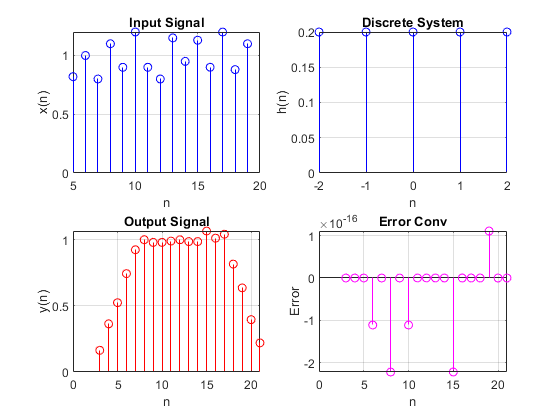

% Sistema que calcula iterativamente 
% la raíz cuadrada de un número MAYOR QUE 1;
% y(n)=0.5*[y(n-1)+x(n)/y(n-1)];
% x(n)=a u(n); donde  a>1 es la entrada.
clc; clear all; close all;

% Entrada x(n)=A u(n), L , y(n-1)
dlg_title = 'Operación?';
prompt = { 'Entrada A:','Duración L de x(n):','y(n-1):'};

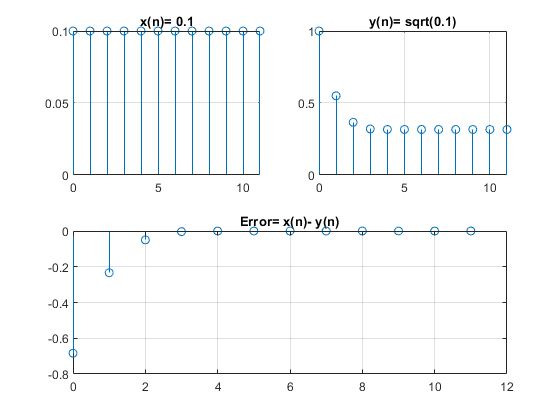

num_lines = 1;
defaultans = {'2', '12', '1'};
answer = inputdlg(prompt,dlg_title,num_lines,defaultans);

% Obtención de x(n)=A u(n), L , y(n-1) 
a=str2num(answer{1});
L=str2num(answer{2});   
yini=str2num(answer{3}); 

x=a*ones(1,L);
if a==0
   errordlg('Error: a debe SER MAYOR A CERO','Valor Error'); 
end    
% Valor de y(0)
n=0; m=n+1;
y(m)=yini ; 
%n=0; m=n+1;

for n=1:L-1
   m=n+1;
   y(m)=0.5*(y(m-1)+x(m)./y(m-1));
end
Err_raiz=sqrt(a)-y; %Error en cada iteración;
subplot(2,2,1); stem([0:L-1],x); title(['x(n)= '  num2str(a)]); grid on;
subplot(2,2,2); stem([0:L-1],y); title(['y(n)= sqrt(' num2str(a) ')']);grid on;
subplot(2,2,3:4);stem([0:L-1],Err_raiz); title('Error= x(n)- y(n)');
grid on;



